## In the name of Allah

## Project 1:

## Hossein Alizadeh Piralidehi 810100522

## Part a)

### Problem considerations:


$$\begin{array}{l}
x_t \in R^n \;t=1,2,\ldotp \ldotp \ldotp ,T\\
x_t \sim N\left(0,a_{t\;} \Sigma \right)\\
x_t \sqcup x_s \;\;\;\;\textrm{for}\;t\not= s\\
a_t \in \;R_+ \\
\lambda \in R_+ 
\end{array}$$


### Constraints:

we want to maximize log-lokelihood function or equivalently minimize -log-likelihood function.

plus a regularization term in objective considered which is:   $\lambda \;\sum_{t=1}^{T-1} \left(\log \;a_{t+1\;} -\log \;a_t {\left.\right)}^2 \right.$

now likelihood function can be written:


$$\begin{array}{l}
f\left(x_t |a_t \right)=\frac{1}{{\left(2\pi \right)}^{\frac{n}{2}} |a_t \Sigma |}\exp \left\lbrace -\frac{1}{2}x_t^T {\left(a_t \Sigma \right)}^{-1} x_t \right\rbrace \\
\textrm{now}\;\textrm{using}\;\textrm{independency}\;\textrm{between}\;\textrm{different}\;\textrm{times}:\\
f\left(x_1 ,x_2 ,\ldotp \ldotp \ldotp ,x_T |a_1 ,a_2 ,\ldotp \ldotp \ldotp ,a_T \right)=\prod_{t=1}^T f\left(x_t |a_t \right)\\
L\left(a_1 ,\ldotp \ldotp \ldotp ,a_T \right)=\log \;\left(\prod_{t=1}^T f\left(x_t |a_t \right)\right)\\
=\sum_{t=1}^T \log \left(f\left(x_t |a_t \right)\right)=\sum_{t=1}^T -\frac{n}{2\;}\log \;2\pi -\log \;a_t -\log \;|\Sigma |-\frac{1}{2}\frac{\;x_{t\;}^T \Sigma^{-1} x_{t\;} }{\;a_t }
\end{array}$$


by removing constant parameters -log-likelihood function can be written:


$$=\sum_{t=1}^T \log \;a_t +\frac{1}{2}\frac{\;x_{t\;}^T \Sigma^{-1} x_{t\;} }{\;a_t }$$


finally by adding regularization term objective function will be:


$$f_0 \left(a_1 ,\ldotp \ldotp \ldotp ,a_T \right)=\sum_{t=1}^T \log \;a_t +\frac{1}{2}\frac{\;x_{t\;}^T \Sigma^{-1} x_{t\;} }{\;a_t }+\lambda \sum_{t=1}^{T-1} \left(\log \;a_{t+1} -\log \;a_t {\left.\right)}^2 \right.$$


and optimization proble will be written:


$$\begin{array}{l}
\min \;f_0 \left(a_1 ,\ldotp \ldotp \ldotp ,a_T \right)\\
s\ldotp t\ldotp \;a_t \ge 0\;\;\;\;\;t=1,\ldotp \ldotp \ldotp ,T
\end{array}$$


as we see this function is not convex, so we should use change variable method to change it as convex problem.


$$\begin{array}{l}
s_t =\log \;a_t \;\;\;\;\;\;b_t =\frac{1}{2\;}\;x_{t\;}^T \Sigma^{-1} x_{t\;} \\
f_0 \left(s\right)=\sum_{t=1}^T s_t +b_t e^{-s_t } +\lambda \sum_{t=1}^{T-1} {\left(s_{t+1} -s_t \right)}^2 
\end{array}$$


first summation in above formula is convex because exp is covex and st is affine, second term is in form of quadratic so:


$$\begin{array}{l}
f_0 \left(s\right)=1^T \left(s+b\ldotp *e^{-s} \right)+\lambda \;s^T Q\;s\\
s={\left\lbrack s_1 ,\ldotp \ldotp \ldotp ,s_T \right\rbrack }^T \;\;\;\;Q={\left\lbrack \begin{array}{cccccccccc}
1 & -2 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 2 & -2 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 2 & -2 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & \ldotp  & \ldotp  & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & \ldotp  & \ldotp  & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & \ldotp  & \ldotp  & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & \ldotp  & -2 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 2 & -2 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 2 & -2\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1
\end{array}\right\rbrack }_{T*T} 
\end{array}$$


as we said first part is convex, and second part is quadratic with Q matrix, as we Q matrix is an upper traiangular matrix so its eigen values will be its diagonal values, which all of them are positive. So quadratic part will be convex too. 

finally optimization problem will be rewrite:


$$\min \;1^T \left(s+b\ldotp *e^{-s} \right)+\lambda \;s^T Q\;s$$


## Part b)

### Simulation with given parameters:

load parameters

clc;clear;close all;
covar_series_data;
b = zeros(T,1);
for t = 1 : T
    b(t) = 1/2*x(:,t)'*inv(Sigma)*x(:,t);
end

Q = zeros(T,T);
for t = 1 : T
    if (t == 1)
        Q(t,t) = 1;
    elseif (t == T)
        Q(t,t) = 1;
        Q(t-1,t) = -2;
    else
        Q(t,t) = 2;
        Q(t-1,t) = -2;
    end
end

solve convex problem using cvx toolbox

s_01 = optimize(0.01, b, Q, T);

 
Successive approximation method to be employed.
   SDPT3 will be called several times to refine the solution.
   Original size: 41 variables, 20 equality constraints
   10 exponentials add 80 variables, 50 equality constraints
-----------------------------------------------------------------
 Cones  |             Errors              |
Mov/Act | Centering  Exp cone   Poly cone | Status
--------+---------------------------------+---------
 10/ 10 | 1.799e+00  2.878e-01  0.000e+00 | Solved
 10/ 10 | 1.679e-01  2.190e-03  0.000e+00 | Solved
  6/ 10 | 4.128e-03  1.177e-06  0.000e+00 | Solved
  0/  1 | 3.368e-04  5.217e-09  0.000e+00 | Solved
-----------------------------------------------------------------
Status: Solved
Optimal value (cvx_optval): +17.4914
 


s_1 = optimize(1, b, Q, T);

 
Successive approximation method to be employed.
   SDPT3 will be called several times to refine the solution.
   Original size: 41 variables, 20 equality constraints
   10 exponentials add 80 variables, 50 equality constraints
-----------------------------------------------------------------
 Cones  |             Errors              |
Mov/Act | Centering  Exp cone   Poly cone | Status
--------+---------------------------------+---------
 10/ 10 | 1.368e+00  1.631e-01  0.000e+00 | Solved
 10/ 10 | 8.693e-02  5.915e-04  0.000e+00 | Solved
  7/ 10 | 4.241e-03  1.289e-06  0.000e+00 | Solved
  0/  1 | 1.602e-04  1.296e-09  0.000e+00 | Solved
-----------------------------------------------------------------
Status: Solved
Optimal value (cvx_optval): +18.7885
 


s_100 = optimize(100, b, Q, T);

 
Successive approximation method to be employed.
   SDPT3 will be called several times to refine the solution.
   Original size: 41 variables, 20 equality constraints
   10 exponentials add 80 variables, 50 equality constraints
-----------------------------------------------------------------
 Cones  |             Errors              |
Mov/Act | Centering  Exp cone   Poly cone | Status
--------+---------------------------------+---------
 10/ 10 | 1.062e+00  8.592e-02  0.000e+00 | Solved
 10/ 10 | 4.708e-02  1.747e-04  0.000e+00 | Solved
  9/  9 | 5.251e-03  1.883e-06  0.000e+00 | Solved
  0/  7 | 2.454e-04  4.402e-09  0.000e+00 | Solved
-----------------------------------------------------------------
Status: Solved
Optimal value (cvx_optval): +20.3743
 


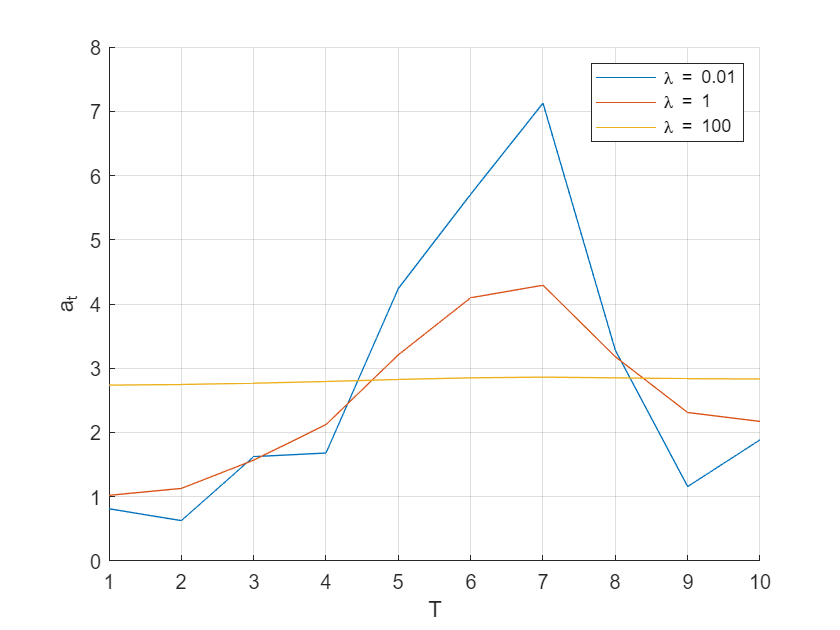

a_01 = exp(s_01); 
a_1 = exp(s_1);
a_100 = exp(s_100);

figure
hold on
grid on
plot(a_01)
plot(a_1)
plot(a_100)
xlabel('T')
ylabel('a_t')
legend('\lambda = 0.01', '\lambda = 1', '\lambda = 100')

## Part c)


$$\sum_{t=1}^T \log \;a_t +\frac{1}{2}\frac{\;x_{t\;}^T \Sigma^{-1} x_{t\;} }{\;a_t }$$


f0_01 = 0;
f0_1 = 0;
f0_100 = 0;
for t = 1 : T
    f0_01 = f0_01 + log(a_01(t)) + 0.5*y(:, t)'*inv(Sigma)*y(:, t)./a_01(t);
    f0_1 = f0_1 + log(a_1(t)) + 0.5*y(:, t)'*inv(Sigma)*y(:, t)./a_1(t);
    f0_100 = f0_100 + log(a_100(t)) + 0.5*y(:, t)'*inv(Sigma)*y(:, t)./a_100(t);
end
f0_01

f0_01 = 18.3816

f0_1

f0_1 = 17.3041

f0_100

f0_100 = 18.5552

objective function for three different lambda (hyper parameter) value shows that lambda = 1 is best choice for this problem.

function s = optimize(lambda, b, Q, T)
    cvx_begin
        variables s(T);
        minimize( ones(1,T)*(s+b.*exp(-s)) + lambda * s'*Q*s );
    cvx_end
end